# Check for Manipulator Self Collisions Using Collision Meshes

This example shows how to check for manipulator self-collisions when executing a trajectory. The collision meshes are loaded via the `<collision>` tag defined in the URDF of a robot model. For more information about how to load collision data in other ways, see [Create Collision Objects for Manipulator Collision Checking](docid:robotics_ug.mw_ac1fd439-ee7d-4bc8-8f58-8d6754597669).

## Create Robot Representation

Import a URDF file of the KUKA® IIWA-14 serial manipulator as a [`rigidBodyTree`](docid:robotics_ref.bvan8uq-1) model. The URDF captures the collision mesh files for the rigid bodies in the robot. To individually add collision objects to a rigid body, you can use the [`addCollision`](docid:robotics_ref#mw_a9f28a02-ea92-4713-bbff-8b58a2b5ab55) function. To load a provided robot model with collision objects attached, see the [`loadrobot`](docid:robotics_ref#mw_5c29228c-fb8f-4ca4-9d7e-eecb323f1a74) function.

iiwa = importrobot('iiwa14.urdf');
iiwa.DataFormat = 'column';

## Generate Trajectory and Check for Collisions

Specify a start and end configuration as a set of joint positions. These positions should be collision free.

startConfig = [0 -pi/4 pi 3*pi/2 0 -pi/2 pi/8]';
goalConfig = [0 -pi/4 pi 3*pi/4 0 -pi/2 pi/8]';

Find a joint space trajectory that connects the two configurations within three seconds.

q = trapveltraj([startConfig goalConfig],100,'EndTime',3);

To verify this output trajectory does not contain self-collisions, iterate over the output samples and see if any points are in collision using the [`checkCollision`](docid:robotics_ref#mw_8986f9e8-12fb-4ce4-970e-fb09ae4d6efb) function. 

While iterating through the trajectory `q`, call the `checkCollision` function on every configuration in the trajectory. Turn on exhaustive checking to continue checking for collisions after the first is detected.

The `isConfigInCollision` variable tracks the collision status of each configuration. The `sepDistForConfig` tracks the separation distance between the bodies of the robot. For each collision, the pair of body indices are stored in the `configCollisionPairs` variable. Note that neighboring bodies are not checked as they are always in contact via the joint that connects them. 

isConfigInCollision = false(100,1);
configCollisionPairs = cell(100,1);
sepDistForConfig = zeros(iiwa.NumBodies+1,iiwa.NumBodies+1,100);
for i = 1:length(q)
    [isColliding, sepDist] = checkCollision(iiwa,q(:,i),'Exhaustive','on','SkippedSelfCollisions','parent');
    isConfigInCollision(i) = isColliding;
    sepDistForConfig(:,:,i) = sepDist;
end

To find out the indices of the bodies in collision, find which entries in the `sepDistForConfig` are `NaN`.  `septDist` is a symmetric matrix, so the same value is returned in indexes with flipped indexes. Simplify the list by using `unique`.

for i = 1:length(q)
    sepDist = sepDistForConfig(:,:,i);
    [body1Idx,body2Idx] = find(isnan(sepDist));

    collidingPairs = unique(sort([body1Idx,body2Idx],2));
    configCollisionPairs{i} = collidingPairs;
end

By inspecting the output, you can see the planned trajectory goes through a series of collisions. Visualize the configuration where the first collision occurs and highlight the bodies.

any(isConfigInCollision)

ans = logical
   1


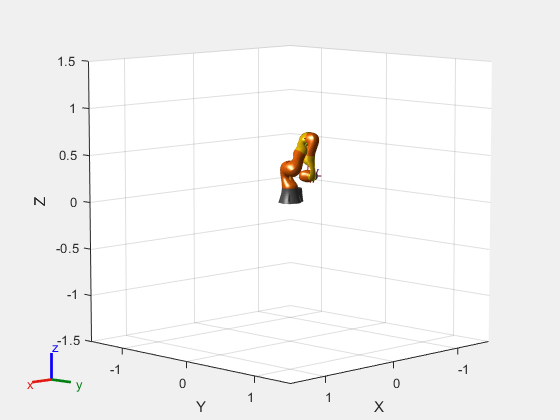

firstCollisionIdx = find(isConfigInCollision,1);

% Visualize the first configuration that is in collision.
figure;
show(iiwa,q(:,firstCollisionIdx));
exampleHelperHighlightCollisionBodies(iiwa,configCollisionPairs{firstCollisionIdx}+1,gca);

## Generate a Collision-Free Trajectory

This first collision actually occurs at the starting configuration because a joint position is specified past its limits. Call `wrapToPi` to limit the starting positions of the joints.

Generate a new trajectory and check for collisions again. 

newStartConfig = wrapToPi(startConfig);
q = trapveltraj([newStartConfig goalConfig],100,'EndTime',3);

isConfigInCollision = false(100,1);
configCollisionPairs = cell(100,1);
for i = 1:length(q)
    isColliding = checkCollision(iiwa,q(:,i),'Exhaustive','on','SkippedSelfCollisions','parent');
    isConfigInCollision(i) = isColliding;
end

After checking the whole trajectory, no collisions are found.

any(isConfigInCollision)

ans = logical
   0


*Copyright 2020-2022 The MathWorks, Inc.*